# Practical3_Q3

## Question Form

An isothermal reactor needs to be designed for a set of parallel homogeneous reactions involving gaseous reactant A and 3 gaseous products B, C and D progresses as follows:


$$\begin{array}{l}
A\to B\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{𝑟𝑒𝑎𝑐𝑡𝑖𝑜n}\;\mathrm{𝑟𝑎𝑡e}\;\;\mathrm{𝑤𝑖𝑡}ℎ\;\mathrm{𝑟𝑒𝑠𝑝𝑒𝑐𝑡}\;\mathrm{𝑡o𝐵},r_B ={\mathrm{kC}}_A^2 \\
A\to C\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{𝑟𝑒𝑎𝑐𝑡𝑖𝑜n}\;\mathrm{𝑟𝑎𝑡e}\;\;\mathrm{𝑤𝑖𝑡}ℎ\;\mathrm{𝑟𝑒𝑠𝑝𝑒𝑐𝑡}\;\mathrm{𝑡o}\;C,r_C ={\mathrm{kC}}_A \\
A\to D\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{𝑟𝑒𝑎𝑐𝑡𝑖𝑜n}\;\mathrm{𝑟𝑎𝑡e}\;\;\mathrm{𝑤𝑖𝑡}ℎ\;\mathrm{𝑟𝑒𝑠𝑝𝑒𝑐𝑡}\;\mathrm{𝑡o}\;D,r_D ={\mathrm{kC}}_A^{0\ldotp 5} 
\end{array}$$


Reactant A is introduced at the reactor inlet with a concentration of 10 mol/m-3. B, C and D product concentrations are **zero** at the inlet. The total volume that should be utilized for the reactor is set to 10 m3 and the volumetric flow rate at the inlet of the reactor has to meet the upstream requirement of 10 m3/hr. Our interest is in **maximizing the yield of the valuable product C**, in comparison to the unwanted products B and D, in the reactor. For simplicity, we consider the gases to be ideal gases and the reaction rates to have equal rate constants k, each equal to 1 m3/mol/hr . Utilizing the ideal reactor formulation, **what is the optimal fraction in which the total given** **reactor volume can be split into a CSTR/PFR in series**, **that will maximize the product C yield for the given flow rate?**

## **Theory**

The yield of B over C is expressed as follows:


$$\frac{\gamma_B }{\gamma_C }=\frac{k_1 }{k_2 }\;\frac{C_A^2 }{C_A }=\frac{k_1 }{k_2 }\;C_A =C_A$$


Three factors affect on decreasing the concentration of reactant: Add inert - Pressure - Mixing

One of the ways to maximize the yield B is making initial concentration of A higher. Using a PFR leads to high yield of B. 

We define a concept called total space time($\tau_{\textrm{tot}} \;$) which consists of a fraction of CSTR behavior (X) and a fraction of PFR behavior (1-X), so:


$$\begin{array}{l}
\tau {\;}_{\mathrm{CSTR}} =X\ldotp \tau_{\mathrm{tot}} \\
\tau_{\mathrm{PFR}} =\left(1-X\right)\tau_{\mathrm{tot}} 
\end{array}$$


clear, clc
global k_r nu
global Q V tau_total tau_cstr tau_pfr c_0
global alpha1 alpha2 alpha3

%reaction orders for parallel reactions 
alpha1 = 2; %B
alpha2 = 1; %C
alpha3 = 0.5; %D
%rate constants for parallel reactions 
k_r=[1 1 1];
%total reactor volume 
V=10; %m3
%stoichiometry matrix
nu=[-1 1 0 0
    -1 0 1 0
    -1 0 0 1];
%initial concentration of reactant in feed
c_0_in=[10 0 0 0];  %mol/m3
%initial concentration at inlet of a reactor
c_0=c_0_in;
%flow rate 
Q=10; %m3/h
%space time for the tubular flow reactor 
tau_total = V/Q;
i=0;

## CSTR + PFR configuration

for frac = 0.001:0.001:0.999
    i = i+1;
    fraction(i) = frac;

    tau_cstr = tau_total * frac;
    tau_pfr  = tau_total * (1- frac);
    %cstr + pfr :
    c_0 = c_0_in;
    y_cstr_2=fsolve('cstr_2',c_0);
    [t,y_pfr_2]=ode23s('pfr_2',[0 tau_pfr],y_cstr_2);
    
    conversion_A(i)=(c_0(1)-y_pfr_2(end,1))/c_0(1);
    
    selectivity_C(i)=y_pfr_2(end,3)/(c_0(1)-y_pfr_2(end,1));
    selectivity_B(i)=y_pfr_2(end,2)/(c_0(1)-y_pfr_2(end,1));
    selectivity_D(i)=y_pfr_2(end,4)/(c_0(1)-y_pfr_2(end,1));

    yield_C_cstr_pfr(i)=conversion_A(i)*selectivity_C(i);
    yield_B_cstr_pfr(i)=conversion_A(i)*selectivity_B(i);
    yield_D_cstr_pfr(i)=conversion_A(i)*selectivity_D(i); 
    clc;
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

## Visualization of Data

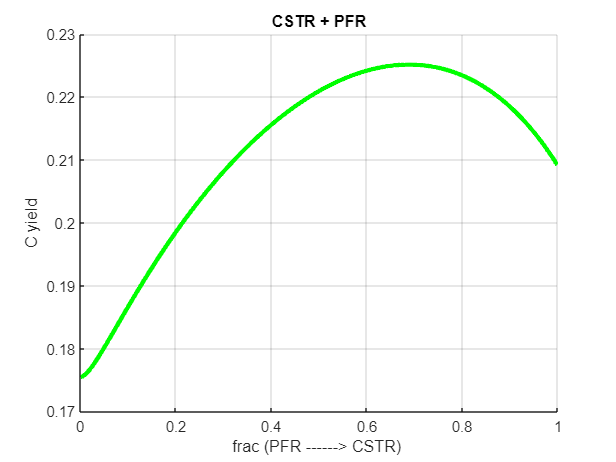

line_color = ['k' 'b' 'g' 'r'];
figure(1);
grid on;
title('CSTR + PFR')
hold on 
%plot(fraction, conversion_A, "Color",line_color(1), 'LineWidth',3)
%plot(fraction, yield_B_cstr_pfr, "Color",line_color(2), 'LineWidth',3)
plot(fraction, yield_C_cstr_pfr, "Color",line_color(3), 'LineWidth',3)
%plot(fraction, yield_D_cstr_pfr, "Color",line_color(4), 'LineWidth',3)
xlabel('frac (PFR ------> CSTR) ');
ylabel('C yield');

%legend('A','B', 'C', 'D')